Exercise 1

data= readtable("norway_new_car_sales_by_make.csv")

data = 4377×5 table
    Year    Month          Make           Quantity    Pct 
    ____    _____    _________________    ________    ____

    2007      1      {'Toyota'       }      2884      22.7
    2007      1      {'Volkswagen'   }      2521      19.9
    2007      1      {'Peugeot'      }      1029       8.1
    2007      1      {'Ford'         }       870       6.9
    2007      1      {'Volvo'        }       693       5.5
    2007      1      {'Skoda'        }       665       5.2
    2007      1      {'Opel'         }       622       4.9
    2007      1      {'Audi'         }       599       4.7
    2007      1      {'Honda'        }       423       3.3
    2007      1      {'Mercedes-Benz'}       362       2.9
    2007      1      {'BMW'          }       352       2.8
    2007      1      {'Citroen'      }    


ind1=find(data(:,1).Year==2014);
ind2=find(data(:,2).Month==2);
ind=intersect(ind1,ind2);

dataFeb2014=data(ind,:);

ind1=find(data(:,1).Year==2015);
ind2=find(data(:,2).Month==2);
ind=intersect(ind1,ind2);

dataFeb2015=data(ind,:);

ind1=find(data(:,1).Year==2016);
ind2=find(data(:,2).Month==2);
ind=intersect(ind1,ind2);

dataFeb2016=data(ind,:);


name = {'Volkswagen', 'Toyota', 'Peugeot', 'Tesla', 'Fiat'};

visData=[]


visData =

     []




for i=1:length(name)
    visData = [visData; 
        dataFeb2014(strcmp(dataFeb2014(:,3).Make,name{i}),4).Quantity,...
        dataFeb2015(strcmp(dataFeb2015(:,3).Make,name{i}),4).Quantity,...
        dataFeb2016(strcmp(dataFeb2016(:,3).Make,name{i}),4).Quantity]
        
end

visData =         1379        1895        2044


visData =         1379        1895        2044
        1352        1436        1374


visData =         1379        1895        2044
        1352        1436        1374
         608         401         428


visData =         1379        1895        2044
        1352        1436        1374
         608         401         428
         431         321         113


visData =         1379        1895        2044
        1352        1436        1374
         608         401         428
         431         321         113
          29          13           5


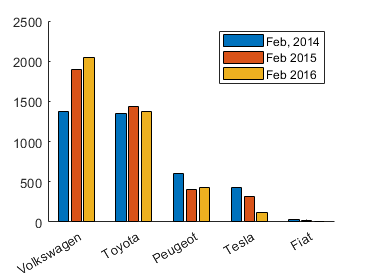


figure()
hold on
bar(visData)
set(gca,'XTick',1:length(name),'XTickLabel',name)
legend('Feb, 2014','Feb 2015','Feb 2016')

Ex2 a

data=readtable('weight-height.csv')

data = 10000×3 table
     Gender     Height    Weight
    ________    ______    ______

    {'Male'}    73.847    241.89
    {'Male'}    68.782    162.31
    {'Male'}     74.11    212.74
    {'Male'}    71.731    220.04
    {'Male'}    69.882    206.35
    {'Male'}    67.253    152.21
    {'Male'}    68.785    183.93
    {'Male'}    68.349    167.97
    {'Male'}    67.019    175.93
    {'Male'}    63.456     156.4
    {'Male'}    71.195     186.6
    {'Male'}    71.641    213.74
    {'Male'}    64.766    167.13
    {'Male'}    69.283    189.45
    {'Male'}    69.244    186.43
    {'Male'}    67.646    172.19



fem=find(strcmp(data(:,1).Gender,'Female'))

fem =         5001
        5002
        5003
        5004
        5005
        5006
        5007
        5008
        5009
        5010


mal=find(strcmp(data(:,1).Gender,'Male'))

mal =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


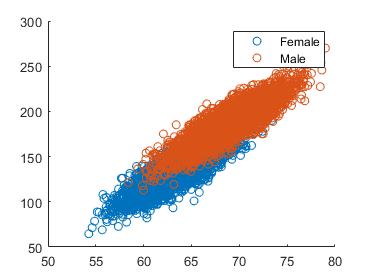


heightF=data(fem,2).Height;
weightF=data(fem,3).Weight;

heightM=data(mal,2).Height;
weightM=data(mal,3).Weight;

figure()
scatter(heightF,weightF)
hold on
scatter(heightM,weightM)
legend('Female','Male')

Exercise 2

data=readtable("Iris.csv")

data = 150×6 table
    Id    SepalLengthCm    SepalWidthCm    PetalLengthCm    PetalWidthCm        Species    
    __    _____________    ____________    _____________    ____________    _______________

     1         5.1             3.5              1.4             0.2         {'Iris-setosa'}
     2         4.9               3              1.4             0.2         {'Iris-setosa'}
     3         4.7             3.2              1.3             0.2         {'Iris-setosa'}
     4         4.6             3.1              1.5             0.2         {'Iris-setosa'}
     5           5             3.6              1.4             0.2         {'Iris-setosa'}
     6         5.4             3.9              1.7             0.4         {'Iris-setosa'}
     7         4.6             3.4      

sl = data ( : , 2 ).SepalLengthCm ;
pl = data ( : , 3 ).SepalWidthCm;
sw = data ( : , 4 ).PetalLengthCm ;
pw = data ( : , 5 ).PetalWidthCm;

spec=data(:,6).Species;

indexse =find(strcmp(spec,'Iris-setosa')==1);
indexve =find(strcmp(spec,'Iris-versicolor')==1);
indexvi =find(strcmp(spec,'Iris-virginica')==1);

datSe = [sl(indexse),pl(indexse),sw(indexse),pw(indexse)]

datSe =     5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000
    5.4000    3.9000    1.7000    0.4000
    4.6000    3.4000    1.4000    0.3000
    5.0000    3.4000    1.5000    0.2000
    4.4000    2.9000    1.4000    0.2000
    4.9000    3.1000    1.5000    0.1000


datVe = [sl(indexve),pl(indexve),sw(indexve),pw(indexve)]

datVe =     7.0000    3.2000    4.7000    1.4000
    6.4000    3.2000    4.5000    1.5000
    6.9000    3.1000    4.9000    1.5000
    5.5000    2.3000    4.0000    1.3000
    6.5000    2.8000    4.6000    1.5000
    5.7000    2.8000    4.5000    1.3000
    6.3000    3.3000    4.7000    1.6000
    4.9000    2.4000    3.3000    1.0000
    6.6000    2.9000    4.6000    1.3000
    5.2000    2.7000    3.9000    1.4000


datVi = [sl(indexvi),pl(indexvi),sw(indexvi),pw(indexvi)]

datVi =     6.3000    3.3000    6.0000    2.5000
    5.8000    2.7000    5.1000    1.9000
    7.1000    3.0000    5.9000    2.1000
    6.3000    2.9000    5.6000    1.8000
    6.5000    3.0000    5.8000    2.2000
    7.6000    3.0000    6.6000    2.1000
    4.9000    2.5000    4.5000    1.7000
    7.3000    2.9000    6.3000    1.8000
    6.7000    2.5000    5.8000    1.8000
    7.2000    3.6000    6.1000    2.5000


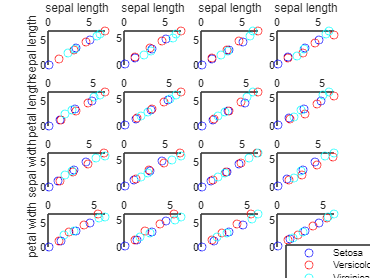


subplot(4,4,1)
scatter(datSe(1,:),datSe(1,:),'b')
hold on
scatter(datVe(1,:),datVe(1,:),'red')
scatter(datVi(1,:),datVi(1,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
xlabel('sepal length')
ylabel('sepal length')


subplot(4,4,2)
scatter(datSe(1,:),datSe(2,:),'b')
hold on
scatter(datVe(1,:),datVe(2,:),'red')
scatter(datVi(1,:),datVi(2,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
xlabel('sepal length')

subplot(4,4,3)
scatter(datSe(1,:),datSe(3,:),'b')
hold on
scatter(datVe(1,:),datVe(3,:),'red')
scatter(datVi(1,:),datVi(3,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
xlabel('sepal length')


subplot(4,4,4)
scatter(datSe(1,:),datSe(4,:),'b')
hold on
scatter(datVe(1,:),datVe(4,:),'red')
scatter(datVi(1,:),datVi(4,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
xlabel('sepal length')



subplot(4,4,3)
scatter(datSe(1,:),datSe(3,:),'b')
hold on
scatter(datVe(1,:),datVe(3,:),'red')
scatter(datVi(1,:),datVi(3,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
xlabel('sepal length')


subplot(4,4,4)
scatter(datSe(1,:),datSe(4,:),'b')
hold on
scatter(datVe(1,:),datVe(4,:),'red')
scatter(datVi(1,:),datVi(4,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
xlabel('sepal length')


subplot(4,4,5)
scatter(datSe(2,:),datSe(1,:),'b')
hold on
scatter(datVe(2,:),datVe(1,:),'red')
scatter(datVi(2,:),datVi(1,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
ylabel('petal length')

subplot(4,4,6)
scatter(datSe(2,:),datSe(2,:),'b')
hold on
scatter(datVe(2,:),datVe(2,:),'red')
scatter(datVi(2,:),datVi(2,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')

subplot(4,4,7)
scatter(datSe(2,:),datSe(3,:),'b')
hold on
scatter(datVe(2,:),datVe(3,:),'red')
scatter(datVi(2,:),datVi(3,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')

subplot(4,4,8)
scatter(datSe(2,:),datSe(4,:),'b')
hold on
scatter(datVe(2,:),datVe(4,:),'red')
scatter(datVi(2,:),datVi(4,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')


subplot(4,4,9)
scatter(datSe(3,:),datSe(1,:),'b')
hold on
scatter(datVe(3,:),datVe(1,:),'red')
scatter(datVi(3,:),datVi(1,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
ylabel('sepal width')

subplot(4,4,10)
scatter(datSe(3,:),datSe(2,:),'b')
hold on
scatter(datVe(3,:),datVe(2,:),'red')
scatter(datVi(3,:),datVi(2,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')

subplot(4,4,11)
scatter(datSe(3,:),datSe(3,:),'b')
hold on
scatter(datVe(3,:),datVe(3,:),'red')
scatter(datVi(3,:),datVi(3,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')

subplot(4,4,12)
scatter(datSe(3,:),datSe(4,:),'b')
hold on
scatter(datVe(3,:),datVe(4,:),'red')
scatter(datVi(3,:),datVi(4,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')

subplot(4,4,13)
scatter(datSe(4,:),datSe(1,:),'b')
hold on
scatter(datVe(4,:),datVe(1,:),'red')
scatter(datVi(4,:),datVi(1,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
ylabel('petal width')

subplot(4,4,14)
scatter(datSe(4,:),datSe(2,:),'b')
hold on
scatter(datVe(4,:),datVe(2,:),'red')
scatter(datVi(4,:),datVi(2,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')

subplot(4,4,15)
scatter(datSe(4,:),datSe(3,:),'b')
hold on
scatter(datVe(4,:),datVe(3,:),'red')
scatter(datVi(4,:),datVi(3,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')


subplot(4,4,16)
scatter(datSe(4,:),datSe(4,:),'b')
hold on
scatter(datVe(4,:),datVe(4,:),'red')
scatter(datVi(4,:),datVi(4,:),'c')
set(gca,'XAxislocation','top','YAxislocation','left')
legend({'Setosa','Versicolor','Virginica'},'Position',[0.85,0,.1,.1])

 Exercise 3

[x,y]=meshgrid(linspace(-1.3,1.3,20),linspace(-1.3,1.3,20))

x =    -1.3000   -1.1632   -1.0263   -0.8895   -0.7526   -0.6158   -0.4789   -0.3421   -0.2053   -0.0684    0.0684    0.2053    0.3421    0.4789    0.6158    0.7526    0.8895    1.0263    1.1632    1.3000
   -1.3000   -1.1632   -1.0263   -0.8895   -0.7526   -0.6158   -0.4789   -0.3421   -0.2053   -0.0684    0.0684    0.2053    0.3421    0.4789    0.6158    0.7526    0.8895    1.0263    1.1632    1.3000
   -1.3000   -1.1632   -1.0263   -0.8895   -0.7526   -0.6158   -0.4789   -0.3421   -0.2053   -0.0684    0.0684    0.2053    0.3421    0.4789    0.6158    0.7526    0.8895    1.0263    1.1632    1.3000
   -1.3000   -1.1632   -1.0263   -0.8895   -0.7526   -0.6158   -0.4789   -0.3421   -0.2053   -0.0684    0.0684    0.2053    0.3421    0.4789    0.6158    0.7526    0.8895    1.0263    1.1632    1.3000
   -1.3000   -1.1632   -1.0263   -0.8895   -0.7526   -0.6158   -0.4789   -0.3421   -0.2053   -0.0684    0.0684    0.2053    0.3421    0.4789    0.6158    0.7526    0.8895    1.0263    1.1632  

y =    -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000   -1.3000
   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632   -1.1632
   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263   -1.0263
   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895   -0.8895
   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526   -0.7526  


z= x.^4.*y.^2 +x.*2.*y.^4 - 3.*x.^2*y.^2+1

z =   -43.3275  -44.2792  -44.7159  -44.7515  -44.4854  -44.0030  -43.3754  -42.6595  -41.8980  -41.1193  -40.3376  -39.5530  -38.7511  -37.9037  -36.9679  -35.8870  -34.5898  -32.9909  -30.9908  -28.4758
  -41.6235  -42.5102  -42.9846  -43.1379  -43.0496  -42.7882  -42.4106  -41.9623  -41.4775  -40.9789  -40.4779  -39.9746  -39.4575  -38.9039  -38.2796  -37.5391  -36.6254  -35.4702  -33.9938  -32.1052
  -40.6047  -41.3814  -41.8372  -42.0429  -42.0606  -41.9434  -41.7358  -41.4732  -41.1821  -40.8803  -40.5766  -40.2711  -39.9549  -39.6103  -39.2106  -38.7204  -38.0954  -37.2824  -36.2194  -34.8354
  -40.0963  -40.7364  -41.1355  -41.3468  -41.4168  -41.3856  -41.2864  -41.1459  -40.9840  -40.8141  -40.6428  -40.4701  -40.2893  -40.0872  -39.8438  -39.5324  -39.1197  -38.5658  -37.8242  -36.8414
  -39.9449  -40.4380  -40.7586  -40.9447  -41.0297  -41.0422  -41.0060  -40.9402  -40.8592  -40.7724  -40.6845  -40.5957  -40.5012  -40.3913  -40.2518  -40.0637  -39.8031  -39.4414  -38.9452  

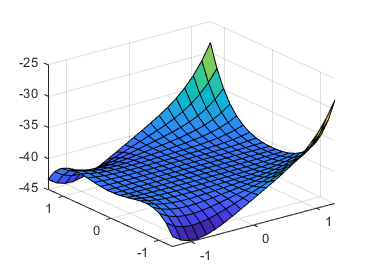


figure()
surf(x,y,z)

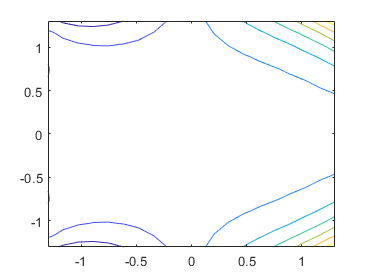

figure()
contour(x,y,z)

Execise 4

data=readtable("Iris.csv")

data = 150×6 table
    Id    SepalLengthCm    SepalWidthCm    PetalLengthCm    PetalWidthCm        Species    
    __    _____________    ____________    _____________    ____________    _______________

     1         5.1             3.5              1.4             0.2         {'Iris-setosa'}
     2         4.9               3              1.4             0.2         {'Iris-setosa'}
     3         4.7             3.2              1.3             0.2         {'Iris-setosa'}
     4         4.6             3.1              1.5             0.2         {'Iris-setosa'}
     5           5             3.6              1.4             0.2         {'Iris-setosa'}
     6         5.4             3.9              1.7             0.4         {'Iris-setosa'}
     7         4.6             3.4      

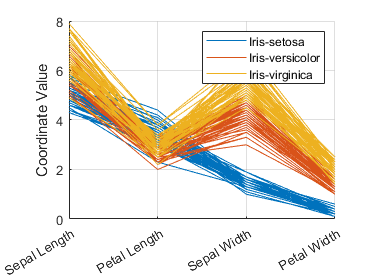


sl=data(:,2).SepalLengthCm;
pl=data(:,3).SepalWidthCm;
sw=data(:,4).PetalLengthCm;
pw=data(:,5).PetalWidthCm;

recData=[sl,pl,sw,pw];

spec=data(:,6).Species;

labels={'Sepal Length','Petal Length','Sepal Width','Petal Width'};

figure()
parallelcoords(recData,'Group',spec,'Labels',labels)
grid on

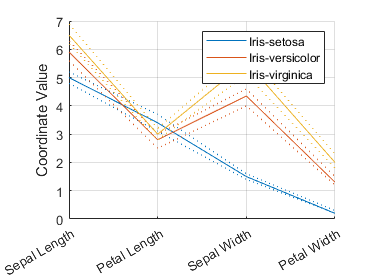


figure()
parallelcoords(recData,'Group',spec,'Labels',labels,'quantile',0.25)
grid on

Exercise 5

clear all
close all
clc

data = readtable('Iris.csv');

sl = data(:,2).SepalLengthCm;
pl = data(:,3).SepalWidthCm;
sw = data(:,4).PetalLengthCm;
pw = data(:,5).PetalWidthCm;

spec = data(:,6).Species;

indxse = find(strcmp(spec,'Iris-setosa') == 1);
indxve = find(strcmp(spec,'Iris-versicolor') == 1);
indxvi = find(strcmp(spec,'Iris-virginica') == 1);

% construct the three data matrices
datSe = [sl(indxse), pl(indxse), sw(indxse), pw(indxse)]'

datSe =     5.1000    4.9000    4.7000    4.6000    5.0000    5.4000    4.6000    5.0000    4.4000    4.9000    5.4000    4.8000    4.8000    4.3000    5.8000    5.7000    5.4000    5.1000    5.7000    5.1000    5.4000    5.1000    4.6000    5.1000    4.8000    5.0000    5.0000    5.2000    5.2000    4.7000    4.8000    5.4000    5.2000    5.5000    4.9000    5.0000    5.5000    4.9000    4.4000    5.1000    5.0000    4.5000    4.4000    5.0000    5.1000    4.8000    5.1000    4.6000    5.3000    5.0000
    3.5000    3.0000    3.2000    3.1000    3.6000    3.9000    3.4000    3.4000    2.9000    3.1000    3.7000    3.4000    3.0000    3.0000    4.0000    4.4000    3.9000    3.5000    3.8000    3.8000    3.4000    3.7000    3.6000    3.3000    3.4000    3.0000    3.4000    3.5000    3.4000    3.2000    3.1000    3.4000    4.1000    4.2000    3.1000    3.2000    3.5000    3.1000    3.0000    3.4000    3.5000    2.3000    3.2000    3.5000    3.8000    3.0000    3.8000    3.2000    3.7000 

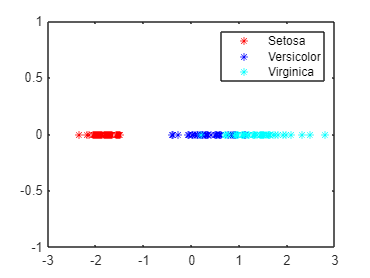

datVe = [sl(indxve), pl(indxve), sw(indxve), pw(indxve)]';
datVi = [sl(indxvi), pl(indxvi), sw(indxvi), pw(indxvi)]';

% compute the centered data matrices
centrum = mean([datSe, datVe, datVi],2);
datSeC = datSe - centrum;
datVeC = datVe - centrum;
datViC = datVi - centrum;

% projection along the axis W_1
v = [1; -1; 1/2; 3/4];
v = v/norm(v);%unit vector
sSe1 = v'* datSeC;
sVe1 = v'* datVeC;
sVi1 = v'* datViC;

figure()
plot(sSe1, zeros(size(sSe1)),'r*')
hold on
plot(sVe1, zeros(size(sVe1)),'b*')
plot(sVi1, zeros(size(sVi1)),'c*')
legend({'Setosa','Versicolor','Virginica'})

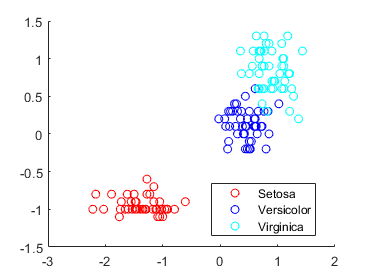


% projection onto the subspace W_2
A = orth([3/5, 0; 3/5, 0; -4/5, 0; 0, -4/5]);
sSe2 = A' * datSeC;
sVe2 = A' * datVeC;
sVi2 = A' * datViC;

figure()
scatter(sSe2(1,:),sSe2(2,:),'r')
hold on
scatter(sVe2(1,:),sVe2(2,:),'b')
scatter(sVi2(1,:),sVi2(2,:),'c')
legend({'Setosa','Versicolor','Virginica'},'location','best')

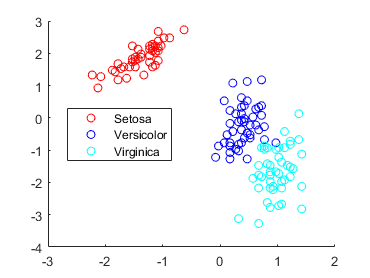


% projection onto the subspace W_3
A2 = orth(null([1, -1, 0, 0; 0, 0, 1, -1]));
sSe3 = A2' * datSeC;
sVe3 = A2' * datVeC;
sVi3 = A2' * datViC;

figure()
scatter(sSe3(1,:),sSe3(2,:),'r')
hold on
scatter(sVe3(1,:),sVe3(2,:),'b')
scatter(sVi3(1,:),sVi3(2,:),'c')
legend({'Setosa','Versicolor','Virginica'},'location','best')

A